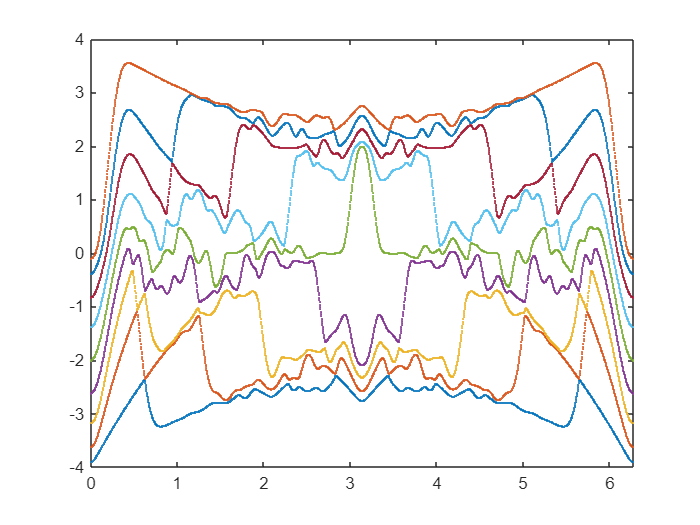



% Magnetic field
N_phi = 2001;
phi = linspace(0,2*pi,N_phi);
Width = 9;
kx_step = 100;
% 
% kx = [-pi,pi];
% 
% kx_list = linspace(kx(1), kx(2),kx_step);
epsilon_0 = 0;
epsilon_Central = 0 * ones(1,Width);
t = 1;
kx =0;
energy_band = zeros(N_phi, Width);
for jj = 1:length(phi)
    energy_band(jj, :) = eig(Hamiltonian_2D_Momentum(kx, Width, epsilon_0, phi(jj), t));
end
p = plot(phi,energy_band,'.',MarkerSize=2);
axis([0,2*pi,-4*t,4*t])







function H = Hamiltonian_2D_Momentum(kx, Width, epsilon, phi, t)
    
    H_00 = epsilon * eye(Width) - t * diag(ones(1, Width-1),1) - t * diag(ones(1, Width-1),-1);
    H_01 = -t * diag(exp(1i * (1:Width) * phi));

    H = H_00 + exp(1i * kx) * H_01 + exp(-1i * kx) * H_01';

end